# Señales y sistemas

Ejemplo de ecuación:


$$\int_{-\infty}^\infty e^{-at} dt$$



$$x = sin(\omega t)$$


## Señales continuas y discretas

Se tomará la covención:

Señal continua := x(t), t variable de tiempo

Las señales discretas := x[n]

## Function Handles vs Simbólicas

%Crear una variable simbólica
syms t

% Función simbólica:
y_symb = cos(t)

$$y\_symb = \cos\left(t\right)$$


%Function handle
%sintaxis: variable = @(parámetro) función
y_fh = @(t) cos(t);

Pero la diferencia más importante es que "function handle" actúa como

una "Lambda de Python" y podemos evaluar facilmente:

y_fh([5 8 10]) 

ans =     0.2837   -0.1455   -0.8391


Pero con las simbólicas no se puede hacer asi y se tiene que utilizar:

% No se puede utilizar sólo la función subs;
% Se tiene que utilizar en conjunto con la función
% "double":
ans_subs_y_symb = subs(y_symb,t,[5 8 10])

$$ans\_subs\_y\_symb = \left(\begin{array}{ccc} \cos\left(5\right) & \cos\left(8\right) & \cos\left(10\right) \end{array}\right)$$

double(ans_subs_y_symb)

ans =     0.2837   -0.1455   -0.8391


Se puede hacer álgebra con variables simbólicas:

y_3 = y_symb + sin(t) + exp(-t)

$$y\_3 = {\mathrm{e}}^{-t}+\cos\left(t\right)+\sin\left(t\right)$$

% Diferenciar
diff(y_3)

$$ans = \cos\left(t\right)-{\mathrm{e}}^{-t}-\sin\left(t\right)$$

% Integrar. Nuevamente, como con la substitución,
% tenemos que utilzar la función "Double" para evaluarla:

ans_int = int(y_3,[0 1])

$$ans\_int = \sin\left(1\right)-{\mathrm{e}}^{-1}-\cos\left(1\right)+2$$

double(ans_int)

ans = 1.9333

int(y_3,t)

$$ans = -{\mathrm{e}}^{-t}-\sqrt{2}\,\cos\left(t+\frac{\pi }{4}\right)$$

No se pueden hacer operaciones con Function Handles:

% y_fh + y_fh Error!

Se pueden convertir las funciones simbólicas en function handles:

y_3_fh = matlabFunction(y_3)

y_3_fh = function_handle with value:
    @(t)exp(-t)+cos(t)+sin(t)


y_3_fh([5 8 10])

ans =    -0.6685    0.8442   -1.3830


## Graficas funciones continuas vs discretas

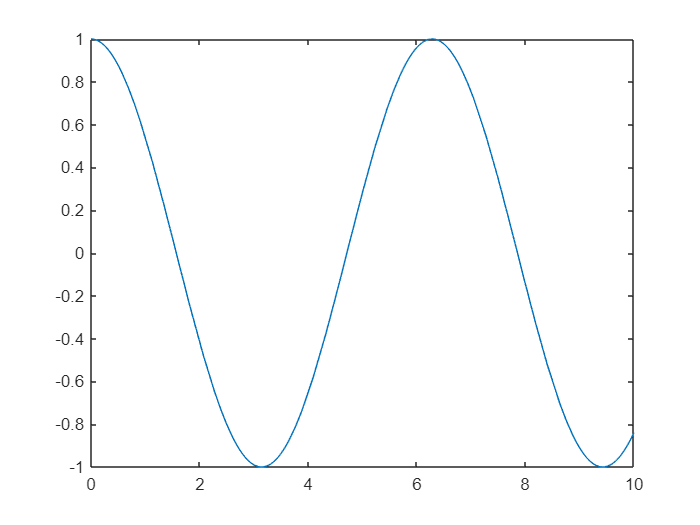

%fplot es para funciones simbólicas
figure
fplot(y_symb,[0,10])

figure
fplot(y_fh,[0,10])

%pasa lo mismo

%el ";" suprime la salida
t_disc = 0:10;

y_disc = y_fh(t_disc)

y_disc =     1.0000    0.5403   -0.4161   -0.9900   -0.6536    0.2837    0.9602    0.7539   -0.1455   -0.9111   -0.8391


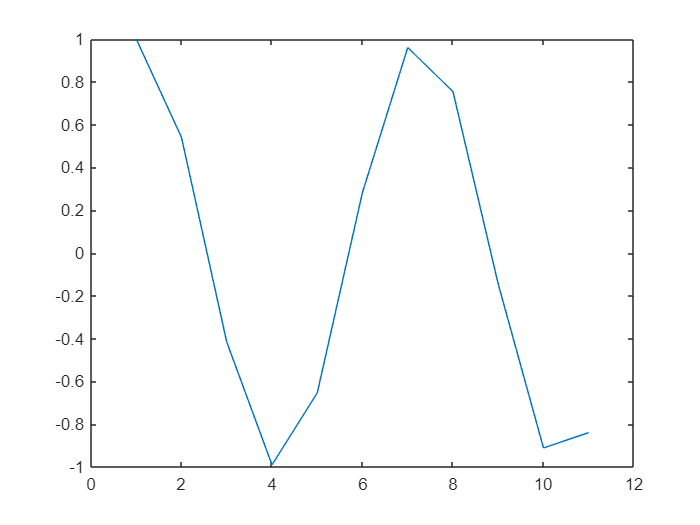

figure
plot(y_disc)

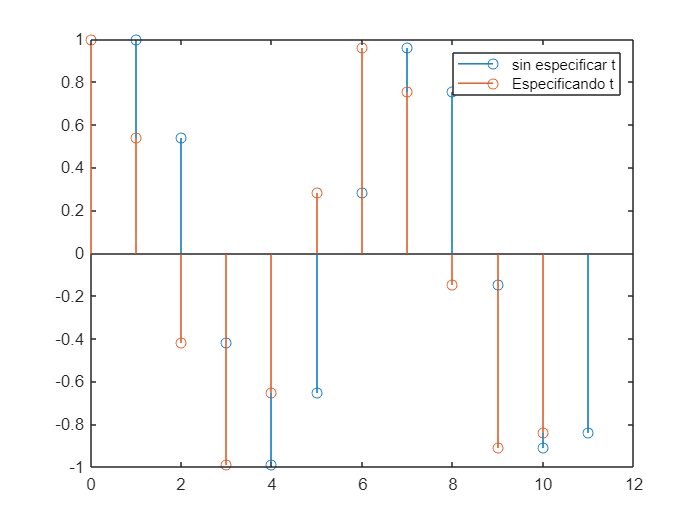

%stem es para muestras o vectores (las líneas verticales. stem=tallo)

%Mostramos que si no especificamos dónde inicia el eje x,
% nuestro plot iniciará desde 1:
figure
stem(y_disc)
hold on
stem(t_disc,y_disc)
hold off
legend("sin especificar t","Especificando t")

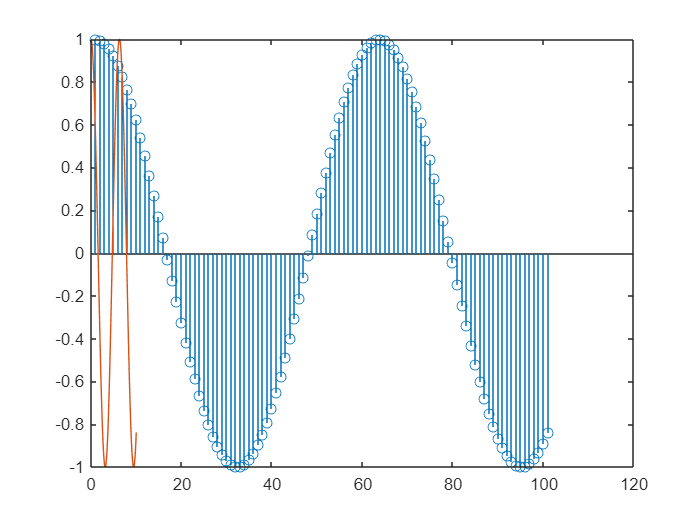

t_disc = 0:0.1:10;
y_disc = y_fh(t_disc);

%Volvemos a ver qué pasa si no specificamos el valor del eje x
figure
stem(y_disc)
hold on
fplot(y_fh,[0,10])
hold off

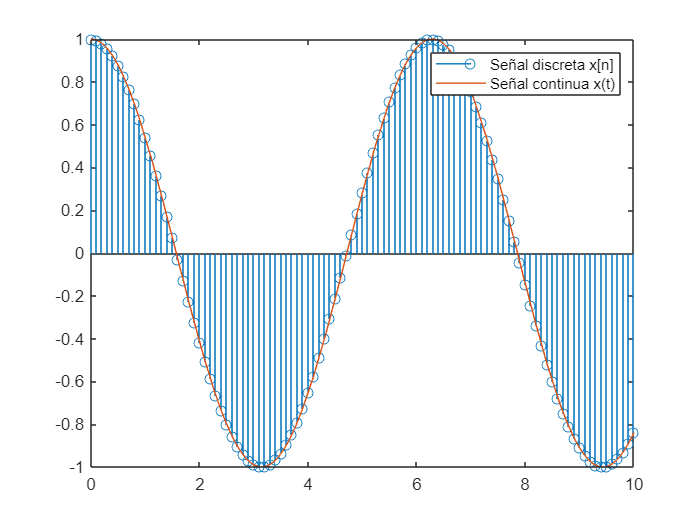

%Si ahora especificamos el eje x:
 
figure
stem(t_disc,y_disc)
hold on
fplot(y_fh,[0,10])
xlim([0,10])
legend("Señal discreta x[n]","Señal continua x(t)")
hold off